#### Time Reversal Visualization

plot the basic setup

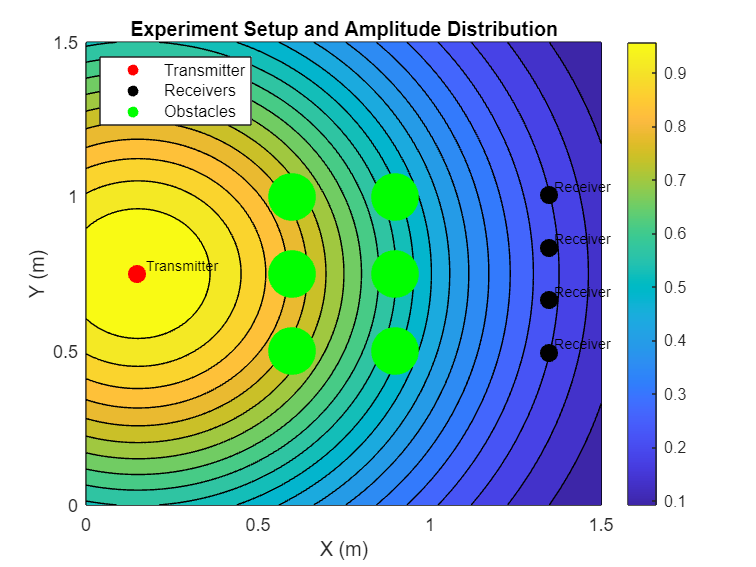

% Define table dimensions
table_length = 1.5;
table_width = 1.5;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.6, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.9, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Simulate amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));
Z = exp(-((X - transmitter_x).^2 + (Y - transmitter_y).^2));

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles
scatter(obstacle_row1_x, obstacle_row1_y, 700, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 700, 'g', 'filled');

% Labeling
title('Experiment Setup and Amplitude Distribution');
xlabel('X (m)');
ylabel('Y (m)');
legend({'','Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

Plot with experimental data of four

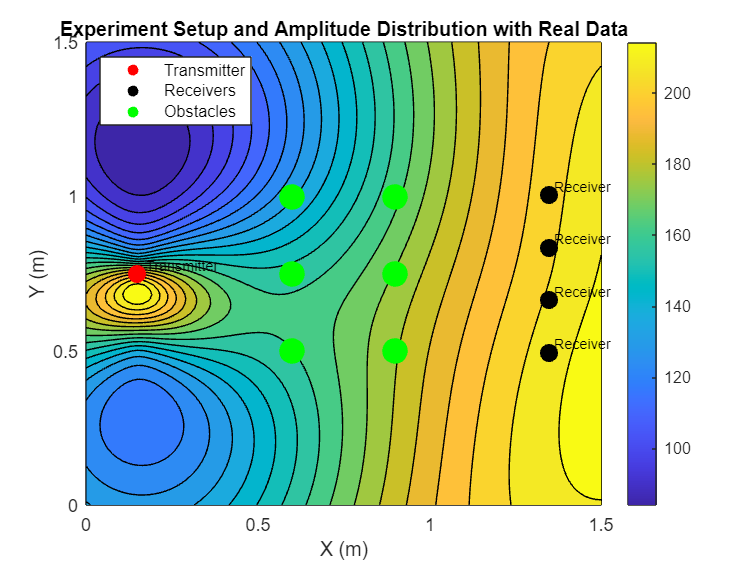

% Define table dimensions
table_length = 1.5;
table_width = 1.5;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.6, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.9, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Real data points
data_points = [
    0.15, 0.75, 194;   % Middle (about origin)
    0.15, 0.8, 146;    % Left Gap
    0.15, 1.0, 91;     % Left
    0.15, 1.25, 86;    % Leftmost
    0.15, 0.5, 142;    % Right
    0.15, 0.7, 220;     % Right Gap
    1.4, 0.75, 210;
];

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Generate grid for amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Interpolate the data points using 'v4' method with griddata
Z = griddata(data_points(:,1), data_points(:,2), data_points(:,3), X, Y, 'v4');

% Fill in NaN values with decreasing values based on distance from data points
for i = 1:numel(Z)
    if isnan(Z(i))
        [min_dist, idx] = min(sqrt((X(i) - data_points(:,1)).^2 + (Y(i) - data_points(:,2)).^2));
        Z(i) = data_points(idx, 3) * exp(-min_dist); % Exponentially decrease
    end
end

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 200, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 200, 'g', 'filled');

% Labeling
title('Experiment Setup and Amplitude Distribution with Real Data');
xlabel('X (m)');
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

Plot adjusted with amplitude near receivers

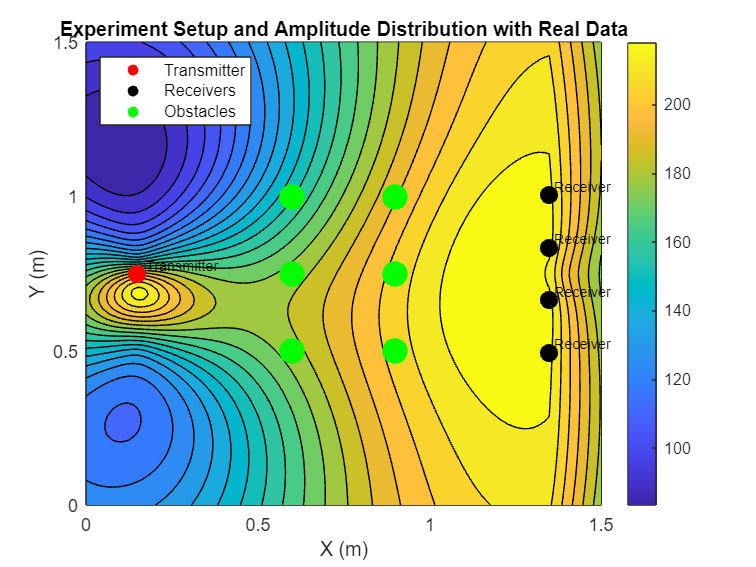

% Define table dimensions
table_length = 1.5;
table_width = 1.5;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.6, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.9, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Real data points
data_points = [
    0.15, 0.75, 194;   % Middle (about origin)
    0.15, 0.8, 146;    % Left Gap
    0.15, 1.0, 91;     % Left
    0.15, 1.25, 86;    % Leftmost
    0.15, 0.5, 142;    % Right
    0.15, 0.7, 220;    % Right Gap
    1.4, 0.75, 210;    % Rightmost
    1.35, 0.4950, 220;
    1.35, 0.665, 220;
    1.35, 0.835, 220;
    1.35, 1.005, 220;
];

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Generate grid for amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Interpolate the data points using 'v4' method with griddata
Z = griddata(data_points(:,1), data_points(:,2), data_points(:,3), X, Y, 'v4');

% Fill in NaN values with decreasing values based on distance from data points
for i = 1:numel(Z)
    if isnan(Z(i))
        [min_dist, idx] = min(sqrt((X(i) - data_points(:,1)).^2 + (Y(i) - data_points(:,2)).^2));
        Z(i) = data_points(idx, 3) * exp(-min_dist); % Exponentially decrease
    end
end

% Make the x points beyond receivers have decreasing amplitude
for i = 1:numel(Z)
    if X(i) > max(receiver_x)
        Z(i) = Z(i) * exp(-(X(i) - max(receiver_x)));
    end
end

% Set all receivers to have amplitude of 220
for i = 1:length(receiver_x)
    Z(abs(X - receiver_x(i)) < 1e-6 & abs(Y - receiver_y(i)) < 1e-6) = 220;
end

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 200, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 200, 'g', 'filled');

% Labeling
title('Experiment Setup and Amplitude Distribution with Real Data');
xlabel('X (m)');
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

rescale table to 1.0 x 1.0 m

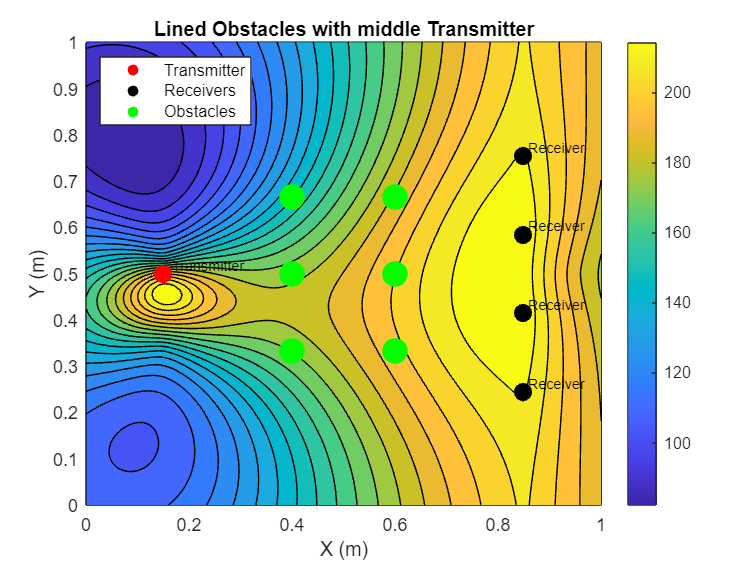

% Define table dimensions
table_length = 1.0;
table_width = 1.0;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.4, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.6, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Real data points
data_points = [
    0.15, 0.75/1.5, 194;   % Middle (about origin)
    0.15, 0.8/1.5, 146;    % Left Gap
    0.15, 1.0/1.5, 91;     % Left
    0.15, 1.25/1.5, 86;    % Leftmost
    0.15, 0.5/1.5, 142;    % Right
    0.15, 0.7/1.5, 220;    % Right Gap
    0.95, 0.75/1.5, 210;    % Rightmost
    0.85, 0.245, 215;
    0.85, 0.415, 220;
    0.85, 0.585, 220;
    0.85, 0.755, 215;
];

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Generate grid for amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Interpolate the data points using 'v4' method with griddata
Z = griddata(data_points(:,1), data_points(:,2), data_points(:,3), X, Y, 'v4');

% Fill in NaN values with decreasing values based on distance from data points
for i = 1:numel(Z)
    if isnan(Z(i))
        [min_dist, idx] = min(sqrt((X(i) - data_points(:,1)).^2 + (Y(i) - data_points(:,2)).^2));
        Z(i) = data_points(idx, 3) * exp(-min_dist); % Exponentially decrease
    end
end

% Make the x points beyond receivers have decreasing amplitude
for i = 1:numel(Z)
    if X(i) > max(receiver_x)
        Z(i) = Z(i) * exp(-(X(i) - max(receiver_x)));
    end
end

% Set all receivers to have amplitude of 220
for i = 1:length(receiver_x)
    Z(abs(X - receiver_x(i)) < 1e-6 & abs(Y - receiver_y(i)) < 1e-6) = 220;
end

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 200, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 200, 'g', 'filled');

% Labeling
title('Lined Obstacles with middle Transmitter');
xlabel('X (m)');
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

with transmitter at upper position

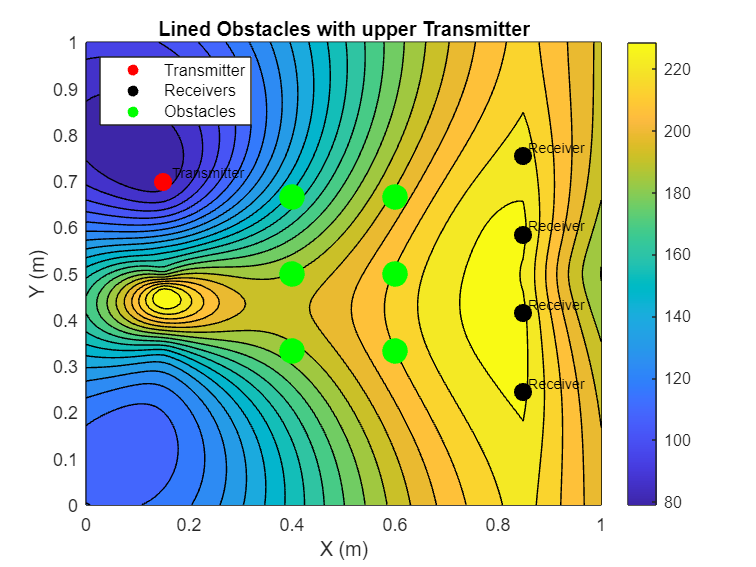

% Define table dimensions
table_length = 1.0;
table_width = 1.0;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = 0.7;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.4, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.6, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Real data points
data_points = [
    0.15, 0.75/1.5, 180;   % Middle (about origin)
    0.15, 0.8/1.5, 160;    % Left Gap
    0.15, 1.0/1.5, 90;     % Left
    0.15, 1.25/1.5, 86;    % Leftmost
    0.15, 0.5/1.5, 152;    % Right
    0.15, 0.7/1.5, 230;    % Right Gap
    0.95, 0.75/1.5, 215;    % Rightmost
    0.85, 0.245, 230;
    0.85, 0.415, 230;
    0.85, 0.585, 230;
    0.85, 0.755, 225;
];

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Generate grid for amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Interpolate the data points using 'v4' method with griddata
Z = griddata(data_points(:,1), data_points(:,2), data_points(:,3), X, Y, 'v4');

% Fill in NaN values with decreasing values based on distance from data points
for i = 1:numel(Z)
    if isnan(Z(i))
        [min_dist, idx] = min(sqrt((X(i) - data_points(:,1)).^2 + (Y(i) - data_points(:,2)).^2));
        Z(i) = data_points(idx, 3) * exp(-min_dist); % Exponentially decrease
    end
end

% Make the x points beyond receivers have decreasing amplitude
for i = 1:numel(Z)
    if X(i) > max(receiver_x)
        Z(i) = Z(i) * exp(-(X(i) - max(receiver_x)));
    end
end

% Set all receivers to have amplitude of 220
for i = 1:length(receiver_x)
    Z(abs(X - receiver_x(i)) < 1e-6 & abs(Y - receiver_y(i)) < 1e-6) = 220;
end

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 200, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 200, 'g', 'filled');

% Labeling
title('Lined Obstacles with upper Transmitter');
xlabel('X (m)');  
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

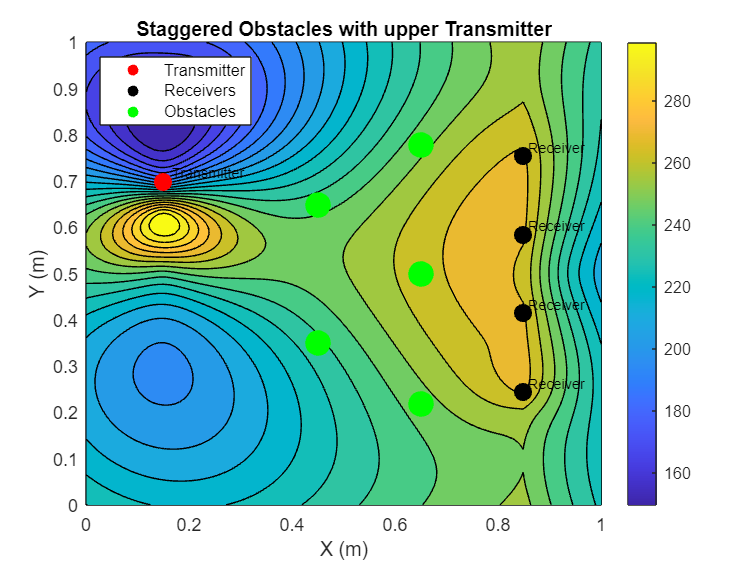

% with staggered obstacles
% Define table dimensions
table_length = 1;
table_width = 1;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = 0.7;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = [0.45, 0.45];
obstacle_row1_y = [0.35, 0.65];
obstacle_row2_x = [0.65, 0.65, 0.65];
obstacle_row2_y = [0.22,0.5,0.78];

% Real data points
data_points = [
    0.15, 0.7, 196;   % origin
    0.15, 0.38, 205;    % right
    0.15, 0.5, 243;     % middle
    0.15, 0.63, 300;    % right of origin
    0.15, 1, 177;    % left
    0.85, 0.2, 260;
    0.85, 0.245, 270;
    0.85, 0.415, 270;
    0.85, 0.585, 270;
    0.85, 0.755, 270;
    0.85, 0.9, 260;
    0.8, 0.35, 270
    0.95, 0.75/1.5, 250;    % R
];

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Generate grid for amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Interpolate the data points using 'v4' method with griddata
Z = griddata(data_points(:,1), data_points(:,2), data_points(:,3), X, Y, 'v4');

% Fill in NaN values with decreasing values based on distance from data points
for i = 1:numel(Z)
    if isnan(Z(i))
        [min_dist, idx] = min(sqrt((X(i) - data_points(:,1)).^2 + (Y(i) - data_points(:,2)).^2));
        Z(i) = data_points(idx, 3) * exp(-min_dist); % Exponentially decrease
    end
end

% Make the x points beyond receivers have decreasing amplitude
for i = 1:numel(Z)
    if X(i) > max(receiver_x)
        Z(i) = Z(i) * exp(-(X(i) - max(receiver_x)));
    end
end

% Set all receivers to have amplitude of 220
for i = 1:length(receiver_x)
    Z(abs(X - receiver_x(i)) < 1e-6 & abs(Y - receiver_y(i)) < 1e-6) = 220;
end

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 200, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 200, 'g', 'filled');

% Labeling
title('Staggered Obstacles with upper Transmitter');
xlabel('X (m)');
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;